# **两次优化**

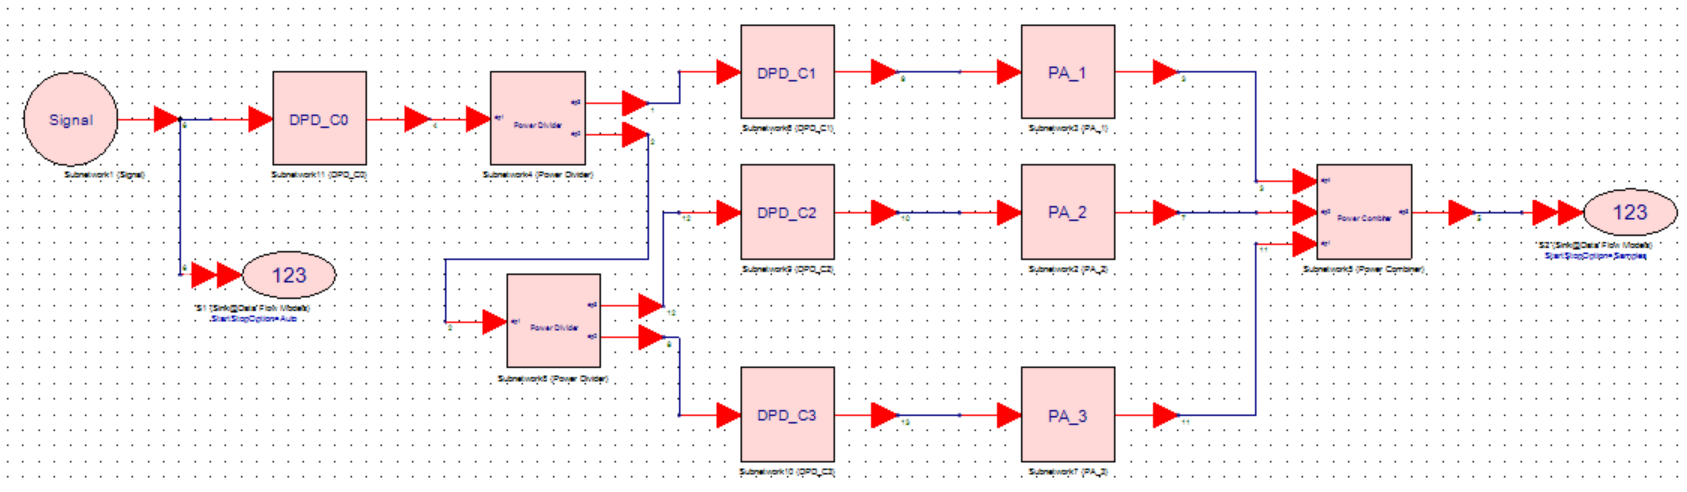

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4); 
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6); 
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8); 
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
M = 4; 

## 【训练PA3】

% 模型训练
model=Train_FNN(M,dim,PA3_input,PA3_output,5);
save('Method_C\PA3\FNN.mat', 'model');

## 【训练PA2】

% 模型训练
model=Train_FNN(M,dim,PA2_input,PA2_output,5);
save('Method_C\PA2\FNN.mat', 'model');

## 【训练PA1】

% 模型训练
model=Train_FNN(M,dim,PA1_input,PA1_output,[8,8]);
save('Method_C\PA1\FNN.mat', 'model');

## 第一次迭代

% 系统仿真
[A1_input,A23] = Power_Divider(Sys_input);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD(A1_input,M,'Method_C\PA1\FNN.mat');
A2_input_DPD = DPD(A2_input,M,'Method_C\PA2\FNN.mat');
A3_input_DPD = DPD(A3_input,M,'Method_C\PA3\FNN.mat');
A1_output = PA_1(A1_input_DPD);
A2_output = PA_2(A2_input_DPD);
A3_output = PA_3(A3_input_DPD);
Sys_output_middle = Power_Combiner(A1_output,A2_output,A3_output);

## 【训练】整体优化

% 训练整体
model=Train_FNN(M,dim,Sys_input,Sys_output_middle,5);
save('Method_C\Whole\FNN.mat', 'model');

## Model Test

% 系统仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_input_DPD = DPD(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
nmse_sim= NMSE_dB(Sys_input,Sys_output);
nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -39.4531

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -37.3678

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -34.6539

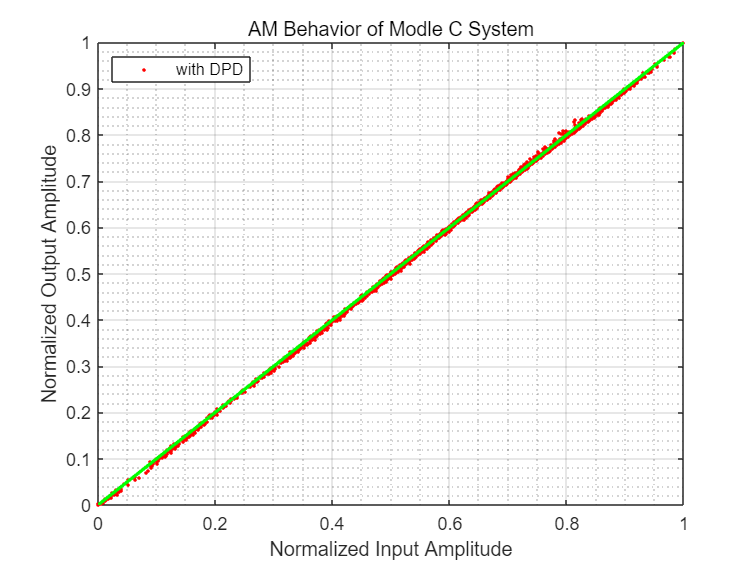

Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');

fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -44.104461 dB


## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 4;

## Model Test

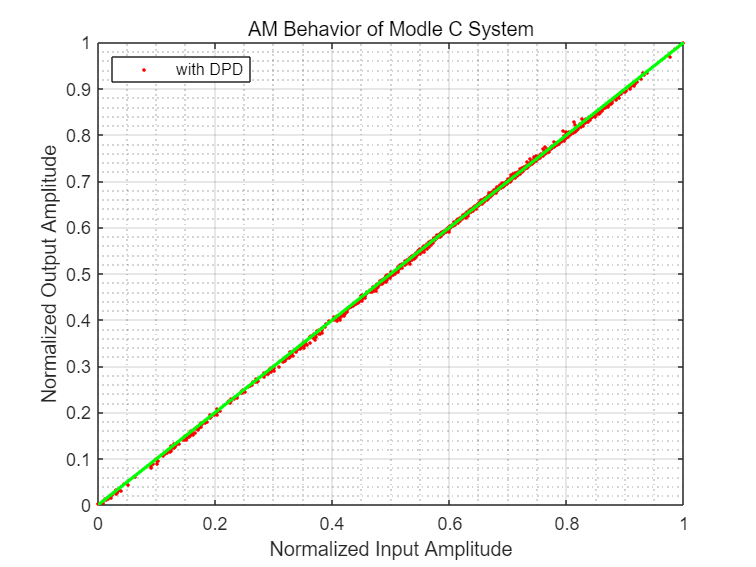

% 系统仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
A2_input_DPD = DPD(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A3_input_DPD = DPD(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_output = PA_2(A2_input_DPD);
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output = Sys_output(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -44.124695 dB
